%1024 

figure1= figure

figure1 =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


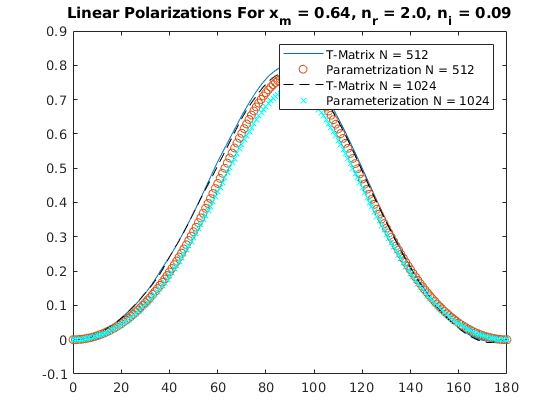

plot(theta,pol_tm512639820009,theta,parpol512_0640_200_009000,'o',theta,pol_tm1024639820009,'k--',theta,parpol1024_0640_200_009000,'cx')
hold on
title('Linear Polarizations For x_m = 0.64, n_r = 2.0, n_i = 0.09' )
legend('T-Matrix N = 512','Parametrization N = 512','T-Matrix N = 1024','Parameterization N = 1024')
hold off


%%%%%%%%%%%%%%%%%% error  %%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%% Polarization %%%%%%%%%%%%
figure2= figure

figure2 =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


errpol_1024639820009 = pol_tm1024639820009 - parpol1024_0640_200_009000

errpol_1024639820009 =          0
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
    0.0001
    0.0008
    0.0020
    0.0035


plot(theta, errpol_1024639820009)
hold on

errpol_512639820009 = pol_tm512639820009 - parpol512_0640_200_009000

errpol_512639820009 =          0
    0.0001
    0.0002
    0.0005
    0.0009
    0.0014
    0.0020
    0.0027
    0.0034
    0.0042


plot(theta, errpol_512639820009)

%errorserror= errpol_1024639820009 -errpol_512639820009

%plot(theta,errorserror)

%256
errpol_256639820009 = (pol_tm256639820009 - parpol256_0640_200_009000)

errpol_256639820009 =          0
    0.0000
    0.0001
    0.0003
    0.0006
    0.0010
    0.0014
    0.0020
    0.0027
    0.0035


plot(theta, errpol_256639820009)


%128
errpol_128639820009 = pol_tm128639820009 - parpol128_0640_200_009000

errpol_128639820009 =          0
    0.0000
    0.0001
    0.0003
    0.0006
    0.0009
    0.0013
    0.0017
    0.0023
    0.0029


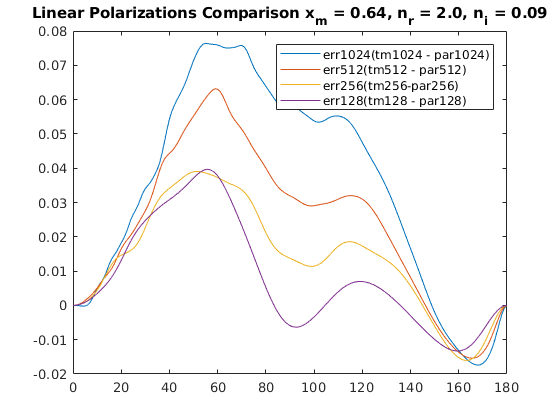

plot(theta, errpol_128639820009)


title('Linear Polarizations Comparison x_m = 0.64, n_r = 2.0, n_i = 0.09' )
legend('err1024(tm1024 - par1024)','err512(tm512 - par512)','err256(tm256-par256)','err128(tm128 - par128)')


%relative error

% figure3= figure
% relerrpol_1024639820009 = (pol_tm1024639820009 - parpol1024_0640_200_009000)./pol_tm1024639820009
% plot(theta, relerrpol_1024639820009)
% hold on
% 
% relerrpol_512639820009 = (pol_tm512639820009 - parpol512_0640_200_009000)./pol_tm512639820009
% plot(theta, relerrpol_512639820009)
% 
% 
% %256
% %relerrpol_256639820009 = (pol_tm256639820009 - parpol256_0640_200_009000)./pol_tm256639820009
% %plot(theta, relerrpol_256639820009)
% 
% %128
% relerrpol_128639820009 = (pol_tm128639820009 - parpol128_0640_200_009000)./pol_tm128639820009
% plot(theta, relerrpol_128639820009)
% 
% 




% title('Linear Polarizations Comparison x_m = 0.64, n_r = 2.0, n_i = 0.09' )
% legend('Rel-err1024','Rel-err512','Rel-err256','Rel-err128')
%

%%%%%%%%%%%%% Phase %%%%%%%%%%%%%%%%%%%

figure4=figure

figure4 =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties




errphs_1024639820009 = S11avg1024639820009 - par1024_0640_200_009000_P11

errphs_1024639820009 =    12.9556
   10.7754
    5.6477
    0.6592
   -1.8469
   -1.7810
   -0.7156
   -0.0969
   -0.1785
   -0.4354


plot(theta, (errphs_1024639820009))
hold on

errphs_512639820009 = S11avg512639820009 - par512_0640_200_009000_P11

errphs_512639820009 =     9.3036
    8.2388
    5.4021
    1.7265
   -1.6736
   -3.9306
   -4.7006
   -4.1860
   -2.9376
   -1.5635


plot(theta, errphs_512639820009)

%errorserror= errpol_1024639820009 -errpol_512639820009

%plot(theta,errorserror)

%256
errphs_256639820009 = S11avg256639820009 - par256_0640_200_009000_P11

errphs_256639820009 =     2.7857
    2.7670
    2.7068
    2.5948
    2.4187
    2.1724
    1.8598
    1.4976
    1.1114
    0.7335


plot(theta, errphs_256639820009)


%128
errphs_128639820009 = S11avg128639820009 - par128_0640_200_009000_P11

errphs_128639820009 =     1.4627
    1.4525
    1.4225
    1.3735
    1.3071
    1.2252
    1.1304
    1.0249
    0.9108
    0.7905


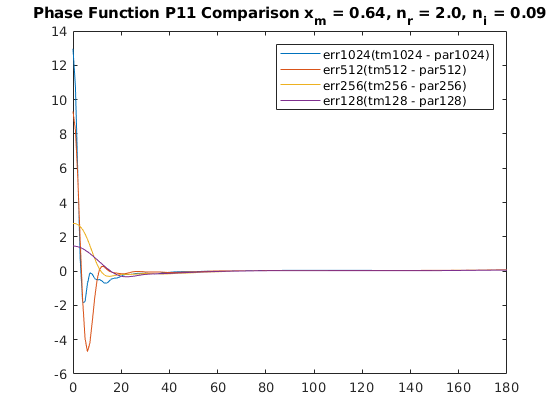

plot(theta, errphs_128639820009)
legend('err1024(tm1024 - par1024)','err512(tm512 - par512)','err256(tm256 - par256)','err128(tm128 - par128)')
title('Phase Function P11 Comparison x_m = 0.64, n_r = 2.0, n_i = 0.09' )




%%%%%%%%%%%%%%%%%%%% partial functions %%%%%%%%%%%%%%%%
%%%%%%%%%%%%% Polarization %%%%%%%%%%%%
theta_90=(0:90)

theta_90 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


figure5=figure

figure5 =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


forerrpol_1024639820009 = pol_tm1024639820009 - parpol1024_0640_200_009000

forerrpol_1024639820009 =          0
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
    0.0001
    0.0008
    0.0020
    0.0035


%f= fit
plot(theta_90, forerrpol_1024639820009(1:91))
hold on

forerrpol_512639820009 = pol_tm512639820009 - parpol512_0640_200_009000

forerrpol_512639820009 =          0
    0.0001
    0.0002
    0.0005
    0.0009
    0.0014
    0.0020
    0.0027
    0.0034
    0.0042


plot(theta_90, forerrpol_512639820009(1:91))

%errorserror= forerrpol_1024639820009 -forerrpol_512639820009

%plot(theta,errorserror)

%256
forerrpol_256639820009 = (pol_tm256639820009 - parpol256_0640_200_009000)

forerrpol_256639820009 =          0
    0.0000
    0.0001
    0.0003
    0.0006
    0.0010
    0.0014
    0.0020
    0.0027
    0.0035


plot(theta_90, forerrpol_256639820009(1:91))


%128
forerrpol_128639820009 = pol_tm128639820009 - parpol128_0640_200_009000

forerrpol_128639820009 =          0
    0.0000
    0.0001
    0.0003
    0.0006
    0.0009
    0.0013
    0.0017
    0.0023
    0.0029


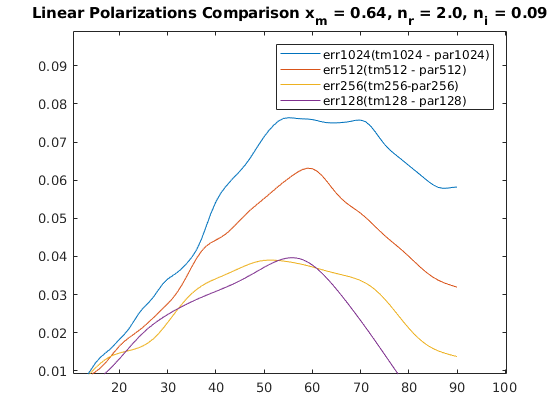

plot(theta_90, forerrpol_128639820009(1:91))


title('Linear Polarizations Comparison x_m = 0.64, n_r = 2.0, n_i = 0.09' )
v.legend('err1024(tm1024 - par1024)','err512(tm512 - par512)','err256(tm256-par256)','err128(tm128 - par128)')



% P22 comparisons

figure6=figure

figure6 =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties




errphs2_1024639820009 = S22avg1024639820009 - par1024_0640_200_009000_P22

errphs2_1024639820009 =  -235.8177
 -223.3495
 -190.4511
 -147.8774
 -106.6795
  -73.6022
  -50.2595
  -35.0419
  -25.4095
  -19.2187


plot(theta, (errphs2_1024639820009))
hold on

errphs2_512639820009 = S22avg512639820009 - par512_0640_200_009000_P22

errphs2_512639820009 =  -127.6817
 -124.2381
 -114.5570
 -100.3746
  -83.9729
  -67.5479
  -52.7334
  -40.4075
  -30.7668
  -23.5520


plot(theta, errphs2_512639820009)

%errorserror= errpol_1024639820009 -errpol_512639820009

%plot(theta,errorserror)

%256
errphs2_256639820009 = S22avg256639820009 - par256_0640_200_009000_P22

errphs2_256639820009 =   -69.6117
  -68.6585
  -65.8912
  -61.5709
  -56.0843
  -49.8826
  -43.4171
  -37.0843
  -31.1882
  -25.9262


plot(theta, errphs2_256639820009)


%128
errphs2_128639820009 = S22avg128639820009 - par128_0640_200_009000_P22

errphs2_128639820009 =   -38.2757
  -38.0090
  -37.2221
  -35.9535
  -34.2632
  -32.2286
  -29.9370
  -27.4801
  -24.9470
  -22.4190


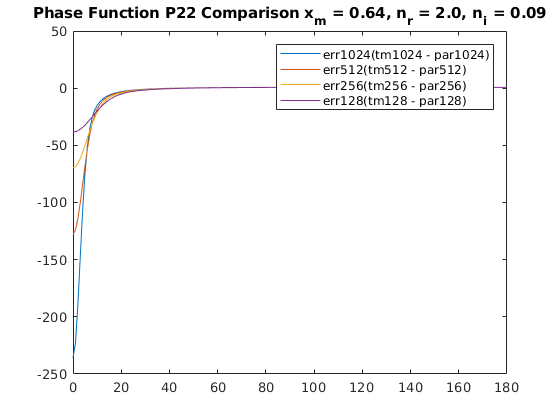

plot(theta, errphs2_128639820009)
legend('err1024(tm1024 - par1024)','err512(tm512 - par512)','err256(tm256 - par256)','err128(tm128 - par128)')
title('Phase Function P22 Comparison x_m = 0.64, n_r = 2.0, n_i = 0.09' )



figure7=figure

figure7 =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


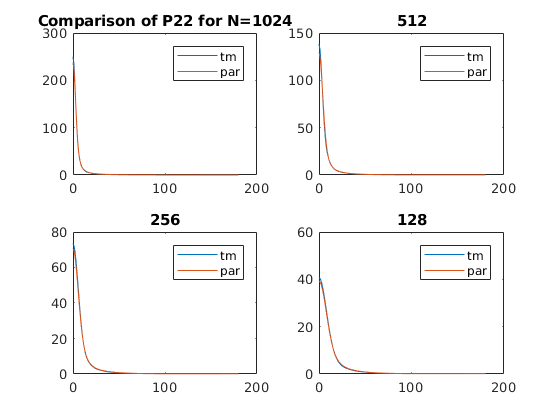

subplot(2,2,1)
plot(theta,S22avg1024639820009.*S11avg1024639820009,theta,par1024_0640_200_009000_P22)
hold on
legend('tm','par')
title('Comparison of P22 for N=1024')
subplot(2,2,2)
plot(theta,S22avg512639820009.*S11avg512639820009,theta,par512_0640_200_009000_P22)
legend('tm','par')
title('512')
subplot(2,2,3)
plot(theta,S22avg256639820009.*S11avg256639820009,theta,par256_0640_200_009000_P22)
legend('tm','par')
title('256')
subplot(2,2,4)
plot(theta,S22avg128639820009.*S11avg128639820009,theta,par128_0640_200_009000_P22)
legend('tm','par')
title('128')


figure8=figure

figure8 =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


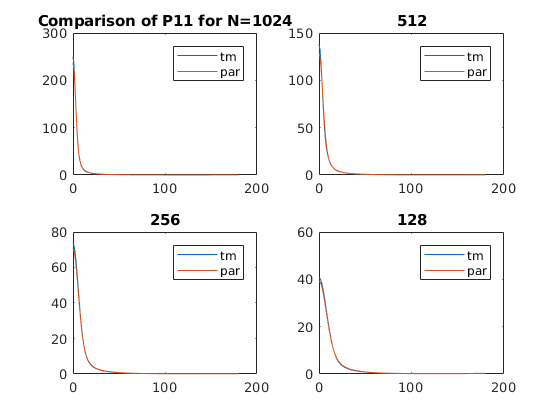

subplot(2,2,1)
plot(theta,S11avg1024639820009,theta,par1024_0640_200_009000_P11)
hold on
legend('tm','par')
title('Comparison of P11 for N=1024')
subplot(2,2,2)
plot(theta,S11avg512639820009,theta,par512_0640_200_009000_P11)
legend('tm','par')
title('512')
subplot(2,2,3)
plot(theta,S11avg256639820009,theta,par256_0640_200_009000_P11)
legend('tm','par')
title('256')
subplot(2,2,4)
plot(theta,S11avg128639820009,theta,par128_0640_200_009000_P11)
legend('tm','par')
title('128')